clc
clear
close all

% VEHICLE PARAMETERS

m = 350;                 % vehicle mass (kg)
r_wheel = 0.25;          % wheel radius (m)
gear = 3.5;              % gear ratio

rho = 1.225;             % air density
Cd = 0.9;                % drag coefficient estimate
A = 1.2;                 % frontal area (m^2)
Crr = 0.015;             % rolling resistance

g = 9.81;



% BATTERY PARAMETERS

V_pack = 100;            % pack voltage
eta_motor = 0.92;        % motor efficiency
eta_inverter = 0.97;

eta_total = eta_motor * eta_inverter;


% MOTOR TORQUE CURVE

rpm_curve = [0 1000 2000 3000 3500 4000 4500 5000];
torque_curve = [78 78 78 78 82 75 68 60];

rpm_max = 5000;


% SIMULATION SETTINGS
 
dt = 0.01;
t_end = 20;
t = 0:dt:t_end;

v = zeros(size(t));
I_batt = zeros(size(t));


% SIMULATION LOOP

for i = 2:length(t)

    % wheel speed
    omega_wheel = v(i-1)/r_wheel;

    % motor rpm
    rpm = omega_wheel * gear * 60/(2*pi);

    if rpm > rpm_max
        torque = 0;
    else
        torque = interp1(rpm_curve,torque_curve,rpm);
    end

    % wheel torque
    T_wheel = torque * gear;

    % traction force
    F_drive = T_wheel / r_wheel;

    % aerodynamic drag
    F_drag = 0.5*rho*Cd*A*v(i-1)^2;

    % rolling resistance
    F_roll = Crr*m*g;

    % net force
    F_net = F_drive - F_drag - F_roll;

    % acceleration
    a = F_net/m;

    % update velocity
    v(i) = v(i-1) + a*dt;

    % mechanical power
    P_mech = F_drive * v(i);

    % electrical power
    P_elec = P_mech / eta_total;

    % battery current

    if V_pack > 0
        I_batt(i) = P_elec / V_pack;
    end

end



% RESULTS

v_kmh = v*3.6;

fprintf("Peak velocity: %.1f km/h\n",max(v_kmh))

Peak velocity: 123.6 km/h


fprintf("Peak battery current: %.0f A\n",max(I_batt))

Peak battery current: 359 A


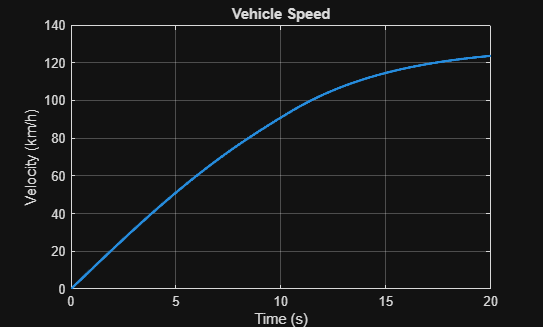


% PLOTS

figure
plot(t,v_kmh,'LineWidth',2)
xlabel('Time (s)')
ylabel('Velocity (km/h)')
title('Vehicle Speed')
grid on

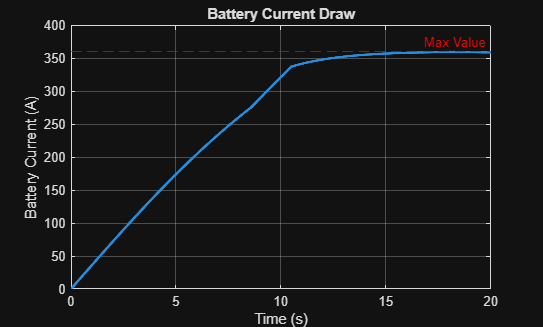


figure
plot(t,I_batt,'LineWidth',2)
xlabel('Time (s)')
ylabel('Battery Current (A)')
title('Battery Current Draw')
yline(max(I_batt), '--r', 'Max Value'); % Draws a dashed red line at the maximum y

grid on